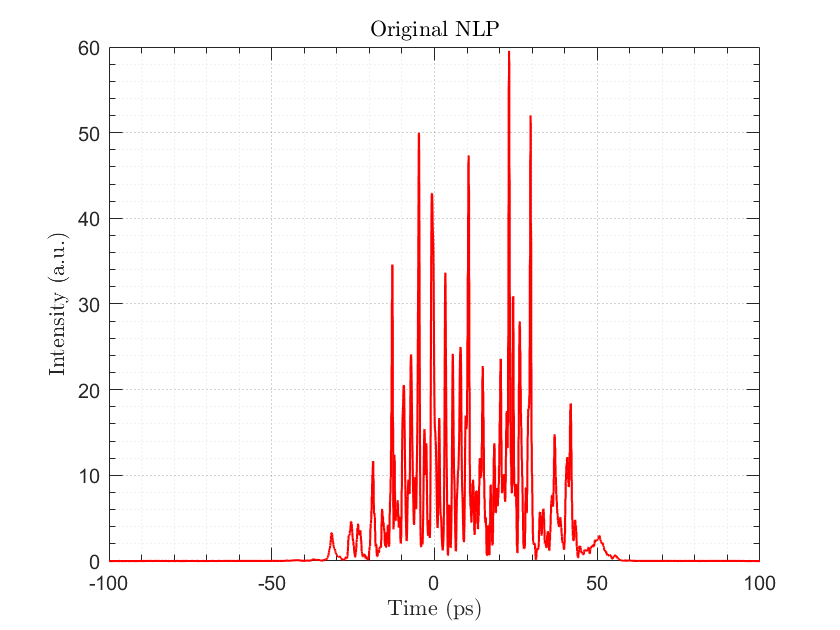

clear
clf
close all 
cd 'C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data';

% ============= NLP Data =============== %
nlpulse = readmatrix("Pulse.txt");
t_ps = nlpulse(:,1)*1e12;

E_N = nlpulse(:,2) + 1j*nlpulse(:,3); 
E_P = nlpulse(:,4) + 1j*nlpulse(:,5);

I_T = abs(E_P).^2 + abs(E_N).^2;

% ====================================== %

% ============= Linear scale plots =============== %
plot(t_ps,I_T, "Color", [1 0 0], 'LineWidth', 1.05)
title('Original NLP',"Interpreter","latex");
xlabel('Time (ps)', "Interpreter","latex");
ylabel('Intensity (a.u.)',"Interpreter","latex");
box on
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid
hold off

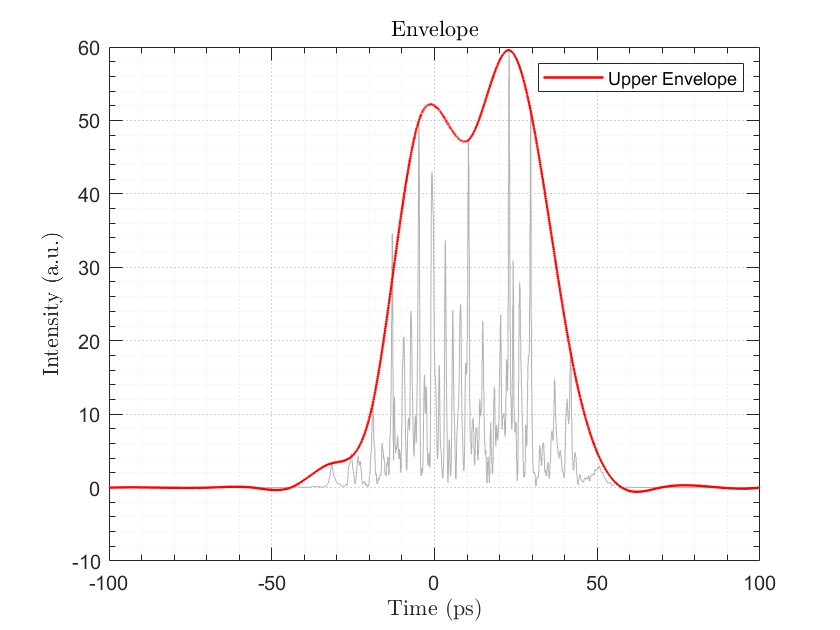


% ===================== Envelope =================%
% Choose window size to match resolution
windowSize = 990;  
[upper_env, lower_env] = envelope(I_T, windowSize, 'peak');

figure;
plot(t_ps, I_T, 'Color',[0.7 0.7 0.7]); hold on
plot(t_ps, upper_env, 'r', 'LineWidth',1.2);
legend('','Upper Envelope');
xlabel('Time (ps)','Interpreter','latex');
ylabel('Intensity (a.u.)','Interpreter','latex');
title('Envelope','Interpreter','latex');
box on
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

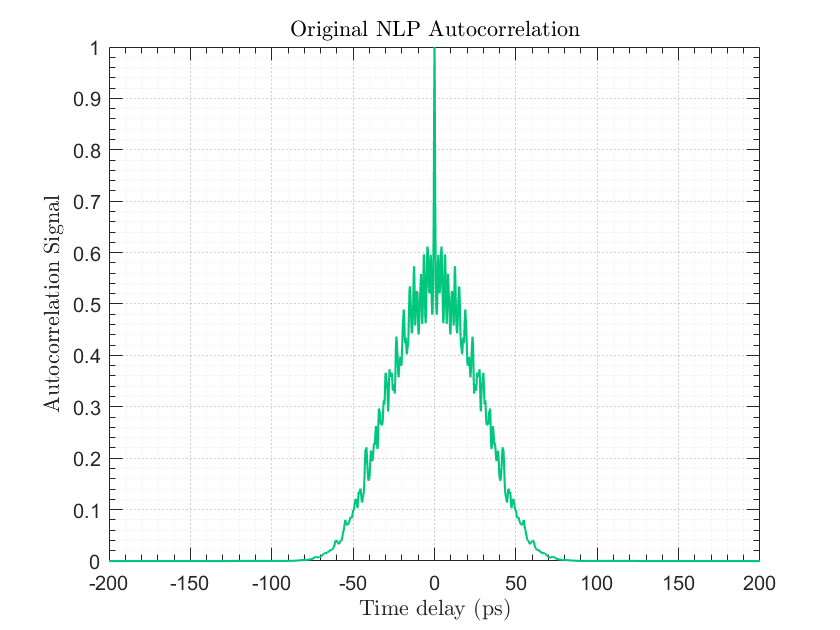



% =============== Auto correlation ================== %
% Compute the sample‐spacing (in ps) lags → time:
dt = mean(diff(t_ps));  

% Compute autocorrelation:
[acf, lags] = xcorr(I_T, 'coeff');  

% Convert lag indices to physical lag times (in ps):
lags_time = lags * dt;  

%Plot:
figure()
plot(lags_time, acf, 'LineWidth', 1.05, 'Color', '#00c77d');
xlabel('Time delay (ps)', 'Interpreter','latex');
ylabel('Autocorrelation Signal', 'Interpreter','latex');
title('Original NLP Autocorrelation', 'Interpreter','latex');
box on
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

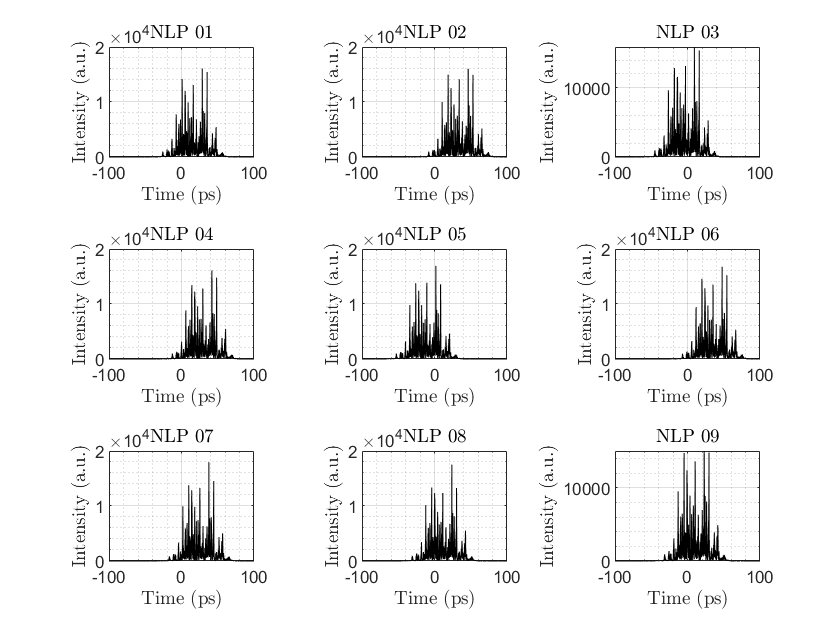

% ============= New NLP's =============== %
M = 50; 
sigma = 8.43;
mu = 9;
time_jitter = 25;
gk_type = 0; % 0 for normal distribution random gain - Any other number for Gaussian
[NLP_Pos, NLP_Neg] = deriveNLPs(E_P, E_N, sigma, mu, M, t_ps, 'shuffle', time_jitter);

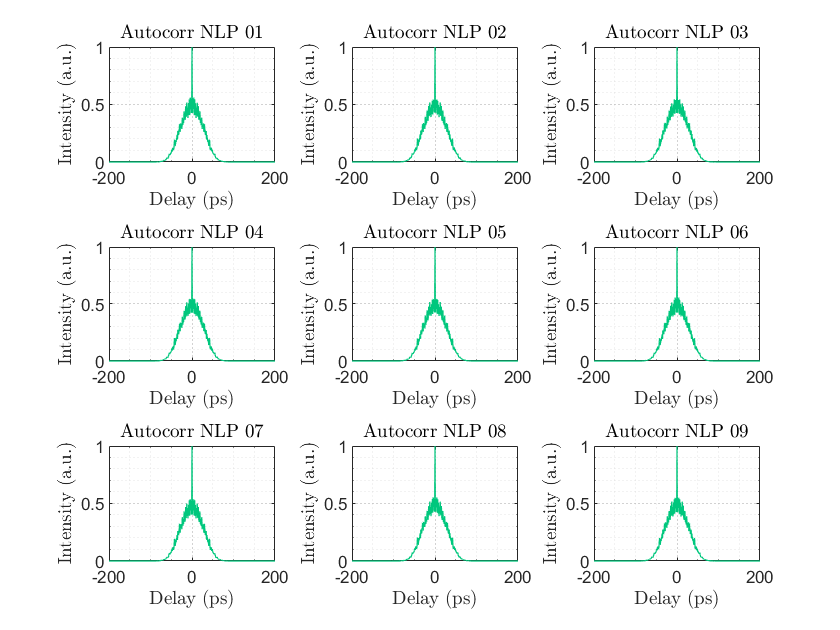

dt = mean(diff(t_ps));       % sample spacing in ps
figure();
tiledlayout(3,3,'TileSpacing','compact');
for k = 1:M
    % retrieve the k-th pulse intensity
    I_k = abs(NLP_Pos(:,k)).^2 + abs(NLP_Neg(:,k)).^2;

    % autocorrelation 
    [acf, lags] = xcorr(I_k, 'coeff');
    tau = lags * dt;  % convert lags to ps

    if(k<10) 
    nexttile;
    plot(tau, acf, 'LineWidth',0.65,'Color','#00c77d');
    title(sprintf('Autocorr NLP 0%d',k),'Interpreter','latex');
    xlabel('Delay (ps)','Interpreter','latex');
    ylabel('Intensity (a.u.)','Interpreter','latex');
    box on
    grid on
    set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
    'TickLength', [0.02, 0.04], ...
    'LineWidth', 0.5);
    grid minor; % Adds minor grid lines
    set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
             'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
             'GridAlpha', 0.7, ...         % Transparency of major grid
             'MinorGridLineStyle', ':', ...% Dotted minor grid lines
             'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
             'MinorGridAlpha', 0.5);       % Transparency of minor grid
    end
end

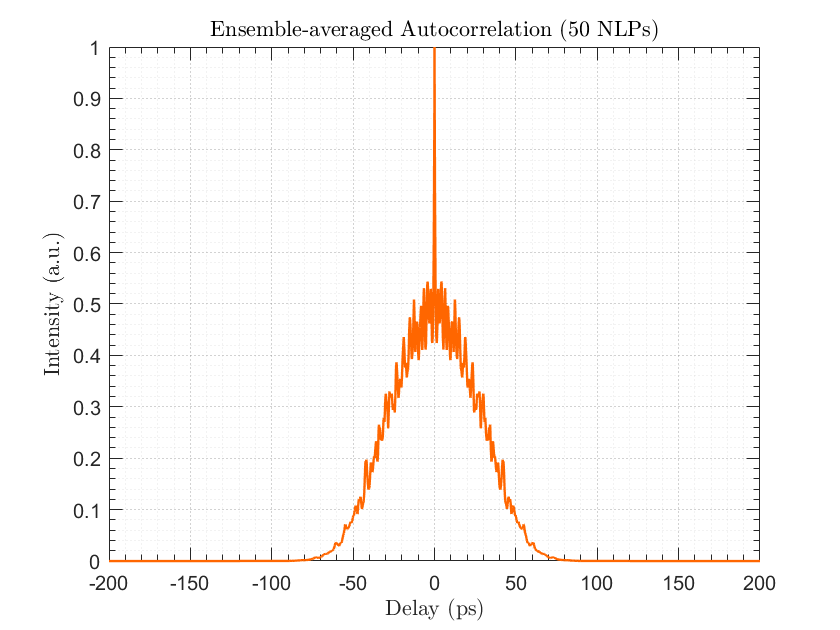



% ================ Global autocorrelation =================%
I_all = abs(NLP_Pos).^2 + abs(NLP_Neg).^2;      
[N, M] = size(I_all);

acf_sum = zeros(2*N-1,1);
for k = 1:M
    acf_k   = xcorr(I_all(:,k), 'coeff');       
    acf_sum = acf_sum + acf_k;
end
acf_mean = acf_sum / M;                       


lags = -(N-1):(N-1);                      % sample lags
tau_ps = lags * dt;                         % delay in ps


figure
plot(tau_ps, acf_mean, 'LineWidth', 1.2, 'Color', '#ff6600');
xlabel('Delay (ps)','Interpreter','latex');
ylabel('Intensity (a.u.)','Interpreter','latex');
title('Ensemble-averaged Autocorrelation (50 NLPs)', 'Interpreter','latex');
box on
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

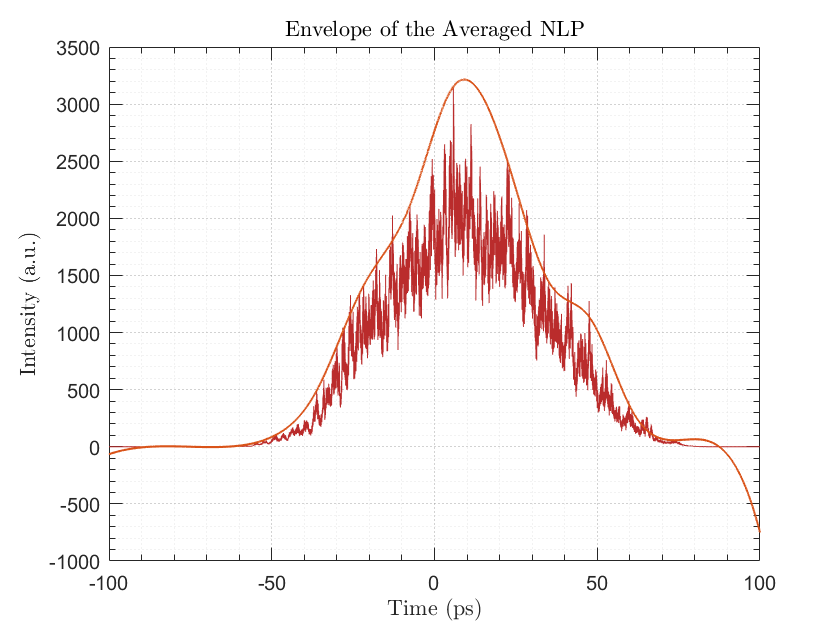


% ================ Averaged NLPs envelope =================%
I_sum = sum(I_all, 2);       
I_mean = I_sum / size(I_all,2);

plot(t_ps, I_mean, 'Color','#ba2c2c'); hold on
xlabel('Time (ps)', 'Interpreter','latex');
ylabel('Intensity (a.u.)', 'Interpreter','latex');
title('Envelope of the Averaged NLP', 'Interpreter','latex');
box on
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

hold off


for i = 1:M
    fname = sprintf('NLPx%d.csv', i);
    SvNLP = [t_ps, NLP_Neg(:,i), NLP_Pos(:,i)];
    writematrix(SvNLP, fname)
end
% =========================================== %




function [NLP_Pos, NLP_Neg] = deriveNLPs(E_P, E_N, sigma, mu, M, t_ps, seed, shiftRange_ps, gk_type)
% deriveNLPs  Genera M nuevos pulsos tipo Noise-Like (NLP) a partir de
%             componentes E(+) y E(–) originales 
%

    arguments
        E_P (:,1)  {mustBeNumeric}
        E_N (:,1)  {mustBeNumeric}
        sigma (1,1) double
        mu    (1,1) double
        M     (1,1) {mustBeInteger,mustBePositive}
        t_ps  (:,1) double = (0:numel(E_P)-1).'   
        seed  double = NaN
        shiftRange_ps (1,1) double = 0
        gk_type (1,1) double = 0
    end
    
     if ~isnan(seed)          
        if isequal(seed,'shuffle')
            rng('shuffle');
        else
            rng(seed);     
        end
    end
    
    % Pre-allocate
    dt = mean(diff(t_ps));             % sample spacing [ps]
    N = numel(E_P);
    NLP_Pos = zeros(N, M);
    NLP_Neg = zeros(N, M);

    % NLP Generation, Autocorrelation and Plotting
    figure()
    tiledlayout(3,3)
    for k = 1:M
        
        if(gk_type == 0) 
        g_k  = sigma * rand(N,1) + mu;  % Normal Distribution Random Gain
        else
        g_k  = mu + sigma * randn(N,1); % Gaussian Distribution Random Gain
        end

        
        if shiftRange_ps > 0
            Delta_t = (2*rand - 1) * shiftRange_ps;     
            nShift  = round(Delta_t / dt);             

            
            Ep_shift = circshift(E_P, nShift);
            En_shift = circshift(E_N, nShift);

            if nShift > 0
                Ep_shift(1:nShift)   = 0;
                En_shift(1:nShift)   = 0;
            elseif nShift < 0
                Ep_shift(end+nShift+1:end) = 0;
                En_shift(end+nShift+1:end) = 0;
            end
        else
            Ep_shift = E_P;
            En_shift = E_N;
        end

        NLP_Pos(:,k) = Ep_shift .* g_k;
        NLP_Neg(:,k) = En_shift .* g_k;
        
        %------------ Intensities ---------------------
        I_total = abs(NLP_Pos(:,k)).^2 + abs(NLP_Neg(:,k)).^2;

        % ---------- Plotting  ----------------------------
        if(k<10) 
        nexttile(k)
        plot(t_ps, I_total, "Color", [0 0 0]); hold on
        title(sprintf('NLP 0%d', k), 'Interpreter','latex')
        xlabel('Time (ps)','Interpreter','latex'); ylabel('Intensity (a.u.)','Interpreter','latex')
        grid on; box on
        set(gca,'XMinorTick','on','YMinorTick','on',...
                'TickLength',[0.02 0.04],'LineWidth',0.5)
        grid minor
        end
    end
    
end


